# DSP Lab - Homework7

#### Mahdi Mahjouri Namin 40023125

#### Nima Nourizadeh 40023086

clc;
clear;
close all;

## Section 3-2 (a)

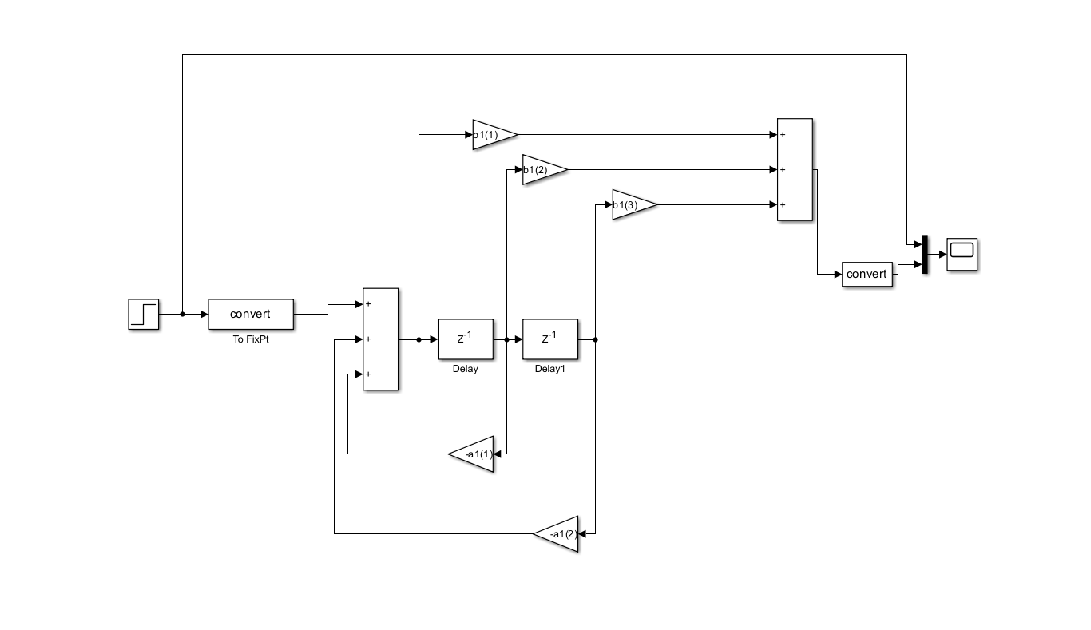


b1 = [0.969531 -1.923772 0.969531];
a1 = [-1.923772 0.939063];

b2 = [0.996088 -1.976468 0.996088];
a2 = [-1.976468 0.992177];


figure('Name', 'Simulink Model of Notch Filter');
imshow('NotchFilterH.png');

## Section 3-2 (b)

### Settling time

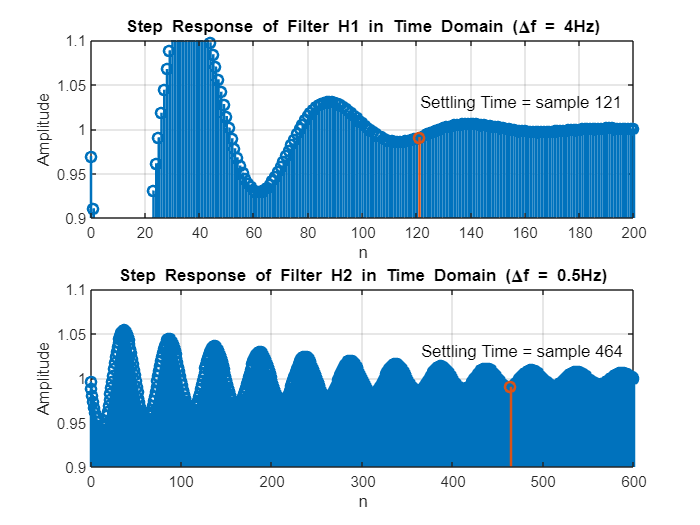


 N = 1e4;
 n = 0:N;
 x_step = ones(1, N + 1);
 w2 = 0;
 w1 = 0;
 x2 = 0;
 x1 = 0;
 y_step = zeros(1, N + 1);
 for i = 1:N + 1

    y_step(i) = -a1(1) * w1 -a1(2) * w2 + b1(1) * x_step(i) + b1(2) * x1 + b1(3) * x2;
    w2 = w1;
    w1 = y_step(i);
    x2 = x1;
    x1 = x_step(i);
 end
 settling_time_value = find(abs(y_step - y_step(end)) >= 0.01, 1, 'last') + 1;
 figure('Name', 'Step Responses of the Two Notch Filters');
 subplot(2, 1 , 1);
 stem(n, y_step, "LineWidth", 1.5);
 title("Step Response of Filter H1 in Time Domain (\Deltaf = 4Hz)");
 xlabel("n");
 ylabel("Amplitude");
 xlim([0 200]);
 ylim([1 - 0.1, 1 + 0.1]);
 grid on;
 hold on;
 stem(settling_time_value - 1, ...
    y_step(settling_time_value), ...
    "LineWidth", 1.5, "Marker", "o");
 text(settling_time_value - 1, ...
    y_step(settling_time_value), ...
    "Settling Time = sample " + (settling_time_value -1), 'position', ...
    [settling_time_value - 1, y_step(settling_time_value) + 0.04]);

 % Step H2
 N = 1e4;
 n = 0:N;
 x_step = ones(1, N + 1);
 w2 = 0;
 w1 = 0;
 x2 = 0;
 x1 = 0;
 y_step_2 = zeros(1, N + 1);
 for i = 1:N + 1

    y_step_2(i) = -a2(1) * w1 -a2(2) * w2 + b2(1) * x_step(i) + b2(2) * x1 + b2(3) * x2;
    w2 = w1;
    w1 = y_step_2(i);
    x2 = x1;
    x1 = x_step(i);
 end
 settling_time_value = find(abs(y_step_2 - y_step_2(end)) >= 0.01, 1, 'last') + 1;
  subplot(2, 1 , 2);
 stem(n, y_step_2, "LineWidth", 1.5);
 title("Step Response of Filter H2 in Time Domain (\Deltaf = 0.5Hz)");
 xlabel("n");
 ylabel("Amplitude");
 xlim([0 600]);
 ylim([1 - 0.1, 1 + 0.1]);
 grid on;
 hold on;
 stem(settling_time_value - 1, ...
    y_step_2(settling_time_value), ...
    "LineWidth", 1.5, "Marker", "o");
 text(settling_time_value - 1, ...
    y_step_2(settling_time_value), ...
    "Settling Time = sample " + (settling_time_value -1), 'position', ...
    [settling_time_value - 100, y_step_2(settling_time_value) + 0.04]);

### Impulse response

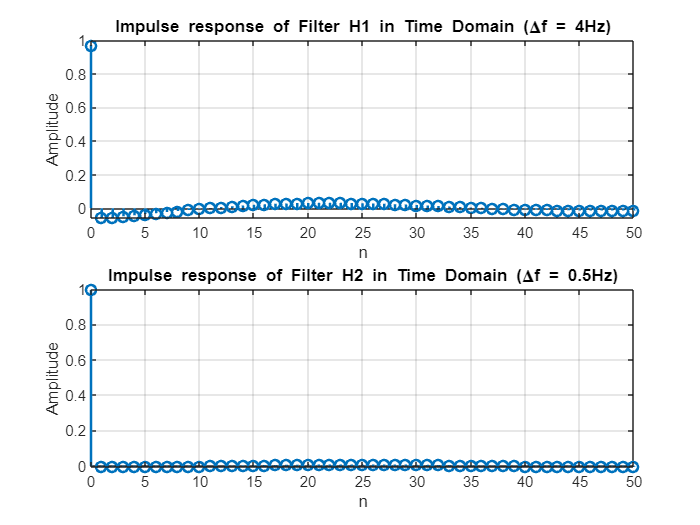

x_delta = zeros(1, N + 1);
x_delta(1) = 1;
w2 = 0;
w1 = 0;
x2 = 0;
x1 = 0;
y_delta = zeros(1, N + 1);
for i = 1:N + 1
    y_delta(i) = -a1(1) * w1 -a1(2) * w2 + b1(1) * x_delta(i) + b1(2) * x1 + b1(3) * x2;
    w2 = w1;
    w1 = y_delta(i);
    x2 = x1;
    x1 = x_delta(i);
end 

w2 = 0;
w1 = 0;
x2 = 0;
x1 = 0;
y_delta_2 = zeros(1, N + 1);
for i = 1:N + 1
    y_delta_2(i) = -a2(1) * w1 -a2(2) * w2 + b2(1) * x_delta(i) + b2(2) * x1 + b2(3) * x2;
    w2 = w1;
    w1 = y_delta_2(i);
    x2 = x1;
    x1 = x_delta(i);
end 
 
figure('Name', 'Impulse Responses of the Two Notch Filters');
subplot(2, 1, 1);
stem(n, y_delta, "LineWidth", 1.5);
title("Impulse response of Filter H1 in Time Domain (\Deltaf = 4Hz)");
xlabel("n");
ylabel("Amplitude");
xlim([0 50]);
grid on;
subplot(2, 1, 2);
stem(n, y_delta_2, "LineWidth", 1.5);
title("Impulse response of Filter H2 in Time Domain (\Deltaf = 0.5Hz)");
xlabel("n");
ylabel("Amplitude");
xlim([0 50]);
grid on;

## Section 3-2 (c)

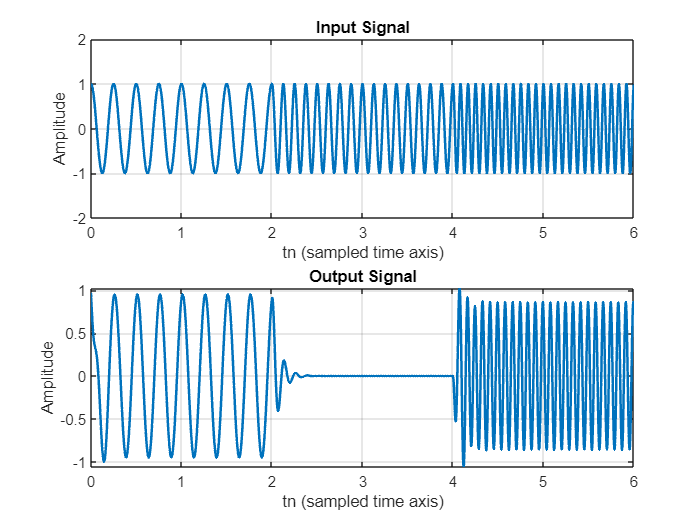


f1 = 4;
f2 = 8;
f3 = 12;
fs = 400;
T = 1/fs;
t = 0:T:6-T;
t1 = 0:T:2-T;
t2 = 0:T:4-T;
t3 = 0:T:6-T;
f = 0:1/f1:20;

% H1 I/O
x_t = cos(2*pi*f1*t).*(t>=0 & t<2) + cos(2*pi*f2*t).*(t>=2 & t<4) + cos(2*pi*f3*t).*(t>=4 & t<6);
y_n = filter(b1,[1 a1],x_t);
figure
subplot(2, 1, 1);
plot(t, x_t, "LineWidth", 1.5);
title("Input Signal")
xlabel("tn (sampled time axis)");
ylabel("Amplitude");
ylim([-2 2])
grid on
subplot(2, 1, 2);
plot(t, y_n, "LineWidth", 1.5);
title("Output Signal")
xlabel("tn (sampled time axis)");
ylabel("Amplitude");
grid on

## Section 3-2 (d)

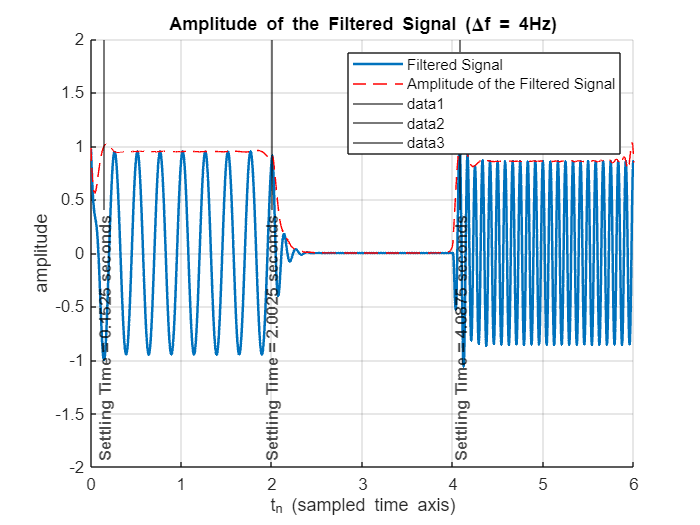


% Compute envelope using Hilbert transform
y_env = abs(hilbert(y_n));

% Compute theoretical |H(f)| at f1 and f3
[H, f] = freqz(b1, a1, 2048, fs);
Hf1 = abs(interp1(f, H, f1));   % |H(f1)| at 4 Hz
Hf2 = abs(interp1(f, H, f2));   % |H(f2)| at 8 Hz
Hf3 = abs(interp1(f, H, f3));   % |H(f3)| at 12 Hz

% Estimate envelope max in each segment
idx1 = find(t >= 0 & t < 2);
idx2 = find(t >= 2 & t < 4);
idx3 = find(t >= 4 & t < 6);
max_env1 = max(y_env(idx1));
max_env2 = max(y_env(idx2));
max_env3 = max(y_env(idx3));

% Find settling time (e.g., within 1% of steady-state)
threshold = 0.01;

settle1 = find(abs(y_env(idx1) - max_env1) < threshold, 1, 'first') / fs;
settle2 = find(abs(y_env(idx2) - max_env2) < threshold, 1, 'first') / fs + 2;
settle3 = find(abs(y_env(idx3) - max_env3) < threshold, 1, 'first') / fs + 4;

% Plot
figure; hold on
plot(t, y_n, 'DisplayName', 'Filtered Signal', "LineWidth", 1.5);
plot(t, y_env, 'r--', 'DisplayName', 'Amplitude of the Filtered Signal');

% Mark settling times
xline(settle1, 'k', ['Settling Time = ' num2str(settle1, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');
xline(settle2, 'k', ['Settling Time = ' num2str(settle2, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');
xline(settle3, 'k', ['Settling Time = ' num2str(settle3, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');

title('Amplitude of the Filtered Signal (\Deltaf = 4Hz)');
xlabel('t_n (sampled time axis)');
ylabel('amplitude');
legend();
grid on;
ylim([-2 2]);

## Section 3-2 (e)

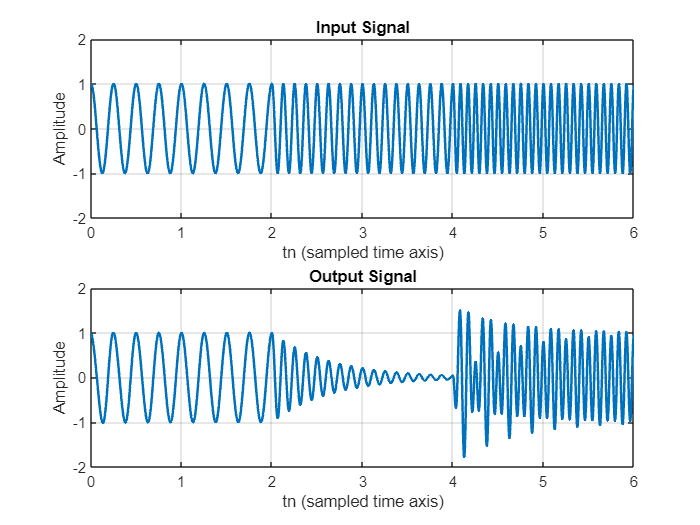

% H2 I/O
y_n_2 = filter(b2,[1 a2],x_t);

figure
subplot(2, 1, 1);
plot(t, x_t, "LineWidth", 1.5);
title("Input Signal")
xlabel("tn (sampled time axis)");
ylabel("Amplitude");
ylim([-2 2])
grid on
subplot(2, 1, 2);
plot(t, y_n_2, "LineWidth", 1.5);
title("Output Signal")
xlabel("tn (sampled time axis)");
ylabel("Amplitude");
grid on

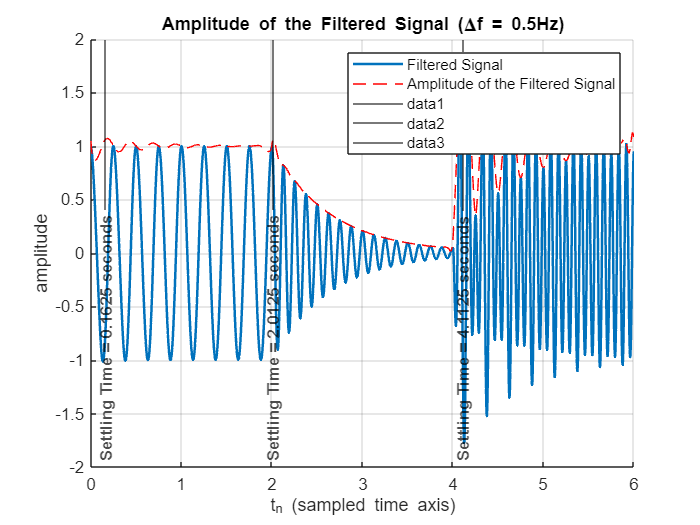

% Repeat section 3-2 (d) for H2

% Compute envelope using Hilbert transform
y_env = abs(hilbert(y_n_2));

% Compute theoretical |H(f)| at f1 and f3
[H, f] = freqz(b2, a2, 2048, fs);
Hf1 = abs(interp1(f, H, f1));   % |H(f1)| at 4 Hz
Hf2 = abs(interp1(f, H, f2));   % |H(f2)| at 8 Hz
Hf3 = abs(interp1(f, H, f3));   % |H(f3)| at 12 Hz

% Estimate envelope max in each segment
idx1 = find(t >= 0 & t < 2);
idx2 = find(t >= 2 & t < 4);
idx3 = find(t >= 4 & t < 6);
max_env1 = max(y_env(idx1));
max_env2 = max(y_env(idx2));
max_env3 = max(y_env(idx3));

% Find settling time (e.g., within 1% of steady-state)
threshold = 0.01;

settle1 = find(abs(y_env(idx1) - max_env1) < threshold, 1, 'first') / fs;
settle2 = find(abs(y_env(idx2) - max_env2) < threshold, 1, 'first') / fs + 2;
settle3 = find(abs(y_env(idx3) - max_env3) < threshold, 1, 'first') / fs + 4;

% Plot
figure; hold on
plot(t, y_n_2, 'DisplayName', 'Filtered Signal', "LineWidth", 1.5);
plot(t, y_env, 'r--', 'DisplayName', 'Amplitude of the Filtered Signal');

% Mark settling times
xline(settle1, 'k', ['Settling Time = ' num2str(settle1, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');
xline(settle2, 'k', ['Settling Time = ' num2str(settle2, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');
xline(settle3, 'k', ['Settling Time = ' num2str(settle3, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');

title('Amplitude of the Filtered Signal (\Deltaf = 0.5Hz)');
xlabel('t_n (sampled time axis)');
ylabel('amplitude');
legend();
grid on;
ylim([-2 2]);

## section 3-2 (f)

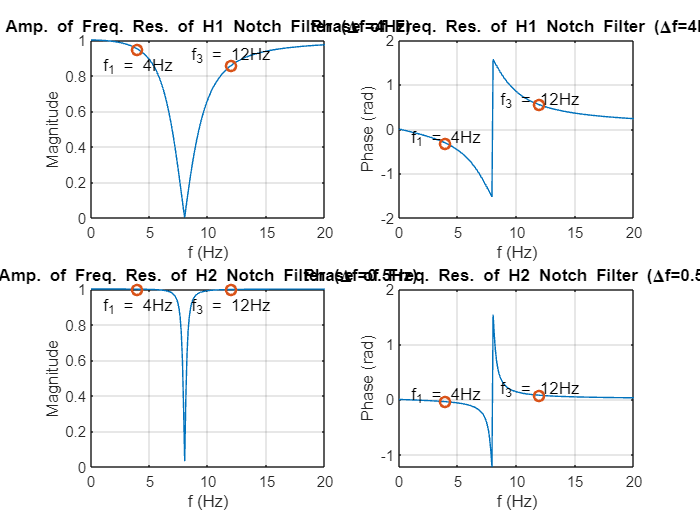

[h1, w] = freqz(b1,[1 a1],f,fs);
[h2, w2] = freqz(b2,[1 a2],f,fs);


H1_f1 = abs(interp1(f, h1, f1));
H1_f3 = abs(interp1(f, h1, f3));
H2_f1 = abs(interp1(f, h2, f1));
H2_f3 = abs(interp1(f, h2, f3));

H1_f1_phase = angle(interp1(f, h1, f1));
H1_f3_phase = angle(interp1(f, h1, f3));
H2_f1_phase = angle(interp1(f, h2, f1));
H2_f3_phase = angle(interp1(f, h2, f3));

% Plot
figure;
subplot(2, 2, 1)
plot(f, abs(h1));
hold on;
plot([f1 f3], [H1_f1 H1_f3], 'o', 'LineWidth',1.5);
text(f1, H1_f1 - 0.1, 'f_1 = 4Hz', 'HorizontalAlignment', 'center');
text(f3, H1_f3 + 0.05, 'f_3 = 12Hz', 'HorizontalAlignment', 'center');
title("Amp. of Freq. Res. of H1 Notch Filter (\Deltaf=4Hz)")
xlabel("f (Hz)");
ylabel("Magnitude");
xlim([0 20]);
grid on

subplot(2, 2, 2);
plot(f, angle(h1));
hold on;
plot([f1 f3], [H1_f1_phase H1_f3_phase], 'o', 'LineWidth',1.5);
text(f1, H1_f1_phase + 0.1, 'f_1 = 4Hz', 'HorizontalAlignment', 'center');
text(f3, H1_f3_phase + 0.1, 'f_3 = 12Hz', 'HorizontalAlignment', 'center');
title("Phase of Freq. Res. of H1 Notch Filter (\Deltaf=4Hz)");
xlabel("f (Hz)");
ylabel("Phase (rad)");
xlim([0 20]);
grid on;

subplot(2, 2, 3)
plot(f, abs(h2));
hold on;
plot([f1 f3], [H2_f1 H2_f3], 'o', 'LineWidth',1.5);
text(f1, H2_f1 - 0.1, 'f_1 = 4Hz', 'HorizontalAlignment', 'center');
text(f3, H2_f3 - 0.1, 'f_3 = 12Hz', 'HorizontalAlignment', 'center');
title("Amp. of Freq. Res. of H2 Notch Filter (\Deltaf=0.5Hz)")
xlabel("f (Hz)");
ylabel("Magnitude");
xlim([0 20]);
grid on

subplot(2, 2, 4);
plot(f, angle(h2));
hold on;
plot([f1 f3], [H2_f1_phase H2_f3_phase], 'o', 'LineWidth',1.5);
text(f1, H2_f1_phase + 0.1, 'f_1 = 4Hz', 'HorizontalAlignment', 'center');
text(f3, H2_f3_phase + 0.1, 'f_3 = 12Hz', 'HorizontalAlignment', 'center');
title("Phase of Freq. Res. of H2 Notch Filter (\Deltaf=0.5Hz)");
xlabel("f (Hz)");
ylabel("Phase (rad)");
xlim([0 20]);
grid on;

## Section 3-2 (g)

threshold = 1/sqrt(2);

% --------------------------
idx_H1 = find(abs(h1) <= threshold+1e-2);
fL_H1 = f(idx_H1(1));
fH_H1 = f(idx_H1(end));
BW_H1 = fH_H1 - fL_H1;

% --------------------------
idx_H2 = find(abs(h2) <= threshold+6e-2);
fL_H2 = f(idx_H2(1));
fH_H2 = f(idx_H2(end));
BW_H2 = fH_H2 - fL_H2;

fprintf('--- H1 Notch Filter ---\n');

--- H1 Notch Filter ---


fprintf('fL = %.2f Hz, fH = %.2f Hz, Δf = %.2f Hz\n', fL_H1, fH_H1, BW_H1);

fL = 6.25 Hz, fH = 10.25 Hz, Δf = 4.00 Hz


fprintf('--- H2 Notch Filter ---\n');

--- H2 Notch Filter ---


fprintf('fL = %.2f Hz, fH = %.2f Hz, Δf = %.2f Hz\n', fL_H2, fH_H2, BW_H2);

fL = 7.71 Hz, fH = 8.30 Hz, Δf = 0.59 Hz


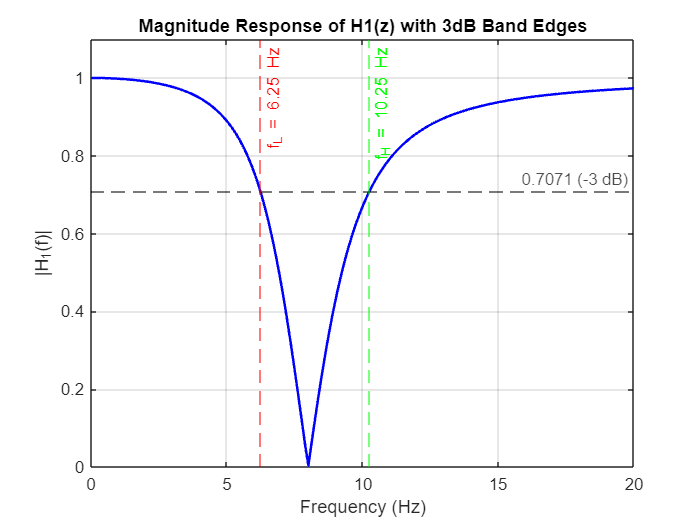

figure;
plot(f, abs(h1), 'b', 'LineWidth', 1.5); hold on;
yline(threshold, 'k--', '0.7071 (-3 dB)');
xline(fL_H1, 'r--', ['f_L = ' num2str(fL_H1, '%.2f') ' Hz']);
xline(fH_H1, 'g--', ['f_H = ' num2str(fH_H1, '%.2f') ' Hz']);
title('Magnitude Response of H1(z) with 3dB Band Edges');
xlabel('Frequency (Hz)');
ylabel('|H_1(f)|');
xlim([0 20]);
grid on;
ylim([0 1.1]);

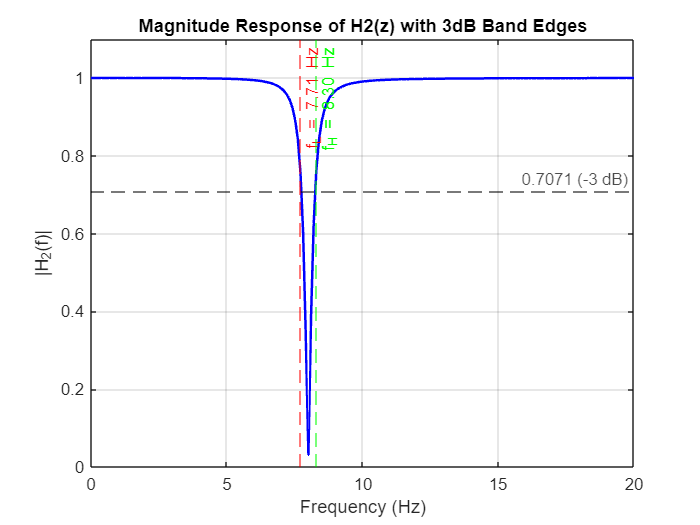

% --------------------------

figure;
plot(f, abs(h2), 'b', 'LineWidth', 1.5); hold on;
yline(threshold, 'k--', '0.7071 (-3 dB)');
xline(fL_H2, 'r--', ['f_L = ' num2str(fL_H2, '%.2f') ' Hz']);
xline(fH_H2, 'g--', ['f_H = ' num2str(fH_H2, '%.2f') ' Hz']);
title('Magnitude Response of H2(z) with 3dB Band Edges');
xlabel('Frequency (Hz)');
ylabel('|H_2(f)|');
xlim([0 20]);
grid on;
ylim([0 1.1]);

## Section 3-2 (h)

Repeat all sections above for the following peak filters:

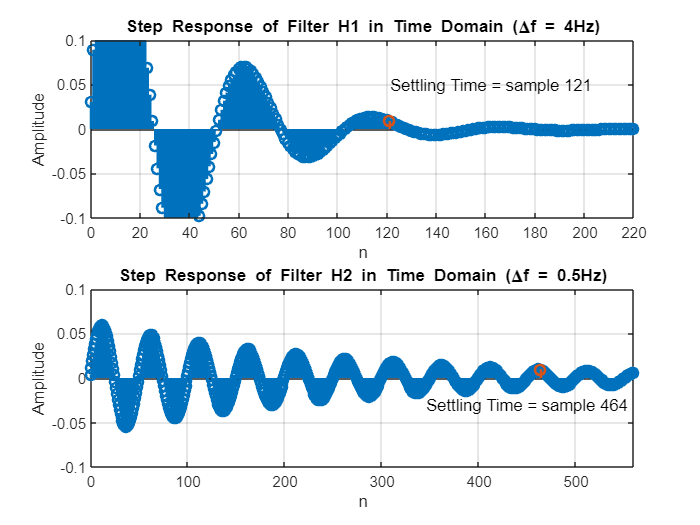

% Coefs of peak filters
b1 = [0.030469 0 -0.030469];
a1 = [-1.923772 0.939063];

b2 = [0.003912 0 -0.003912];
a2 = [-1.976468 0.992177];



 N = 1e4;
 n = 0:N;
 x_step = ones(1, N + 1);
 w2 = 0;
 w1 = 0;
 x2 = 0;
 x1 = 0;
 y_step = zeros(1, N + 1);
 for i = 1:N + 1

    y_step(i) = -a1(1) * w1 -a1(2) * w2 + b1(1) * x_step(i) + b1(2) * x1 + b1(3) * x2;
    w2 = w1;
    w1 = y_step(i);
    x2 = x1;
    x1 = x_step(i);
 end
 settling_time_value = find(abs(y_step - y_step(end)) >= 0.01, 1, 'last') + 1;
 figure('Name', 'Step Responses of the Two Notch Filters');
 subplot(2, 1 , 1);
 stem(n, y_step, "LineWidth", 1.5);
 title("Step Response of Filter H1 in Time Domain (\Deltaf = 4Hz)");
 xlabel("n");
 ylabel("Amplitude");
 xlim([0 220]);
 ylim([0 - 0.1, 0 + 0.1]);
 grid on;
 hold on;
 stem(settling_time_value - 1, ...
    y_step(settling_time_value), ...
    "LineWidth", 1.5, "Marker", "o");
 text(settling_time_value - 1, ...
    y_step(settling_time_value), ...
    "Settling Time = sample " + (settling_time_value -1), 'position', ...
    [settling_time_value - 1, y_step(settling_time_value) + 0.04]);



 % Step H2
 N = 1e4;
 n = 0:N;
 x_step = ones(1, N + 1);
 w2 = 0;
 w1 = 0;
 x2 = 0;
 x1 = 0;
 y_step_2 = zeros(1, N + 1);
 for i = 1:N + 1

    y_step_2(i) = -a2(1) * w1 -a2(2) * w2 + b2(1) * x_step(i) + b2(2) * x1 + b2(3) * x2;
    w2 = w1;
    w1 = y_step_2(i);
    x2 = x1;
    x1 = x_step(i);
 end
 settling_time_value = find(abs(y_step_2 - y_step_2(end)) >= 0.01, 1, 'last') + 1;
  subplot(2, 1 , 2);
 stem(n, y_step_2, "LineWidth", 1.5);
 title("Step Response of Filter H2 in Time Domain (\Deltaf = 0.5Hz)");
 xlabel("n");
 ylabel("Amplitude");
 xlim([0 560]);
 ylim([0 - 0.1, 0 + 0.1]);
 grid on;
 hold on;
 stem(settling_time_value - 1, ...
    y_step_2(settling_time_value), ...
    "LineWidth", 1.5, "Marker", "o");
 text(settling_time_value - 1, ...
    y_step_2(settling_time_value), ...
    "Settling Time = sample " + (settling_time_value -1), 'position', ...
    [settling_time_value - 120, y_step_2(settling_time_value) - 0.04]);

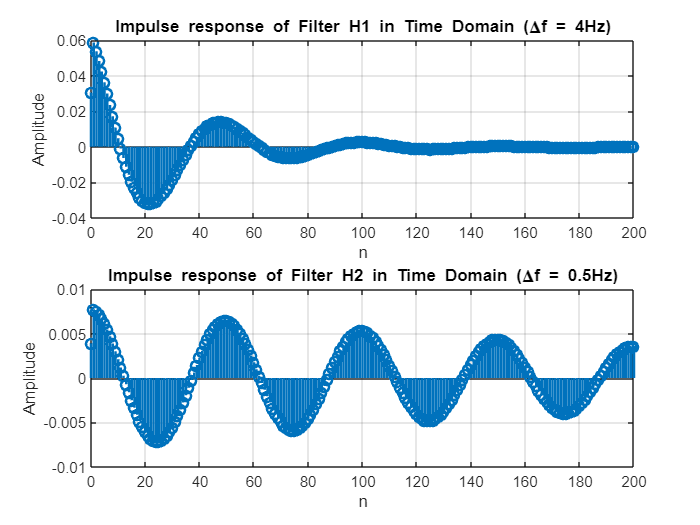

x_delta = zeros(1, N + 1);
x_delta(1) = 1;
w2 = 0;
w1 = 0;
x2 = 0;
x1 = 0;
y_delta = zeros(1, N + 1);
for i = 1:N + 1
    y_delta(i) = -a1(1) * w1 -a1(2) * w2 + b1(1) * x_delta(i) + b1(2) * x1 + b1(3) * x2;
    w2 = w1;
    w1 = y_delta(i);
    x2 = x1;
    x1 = x_delta(i);
end 

w2 = 0;
w1 = 0;
x2 = 0;
x1 = 0;
y_delta_2 = zeros(1, N + 1);
for i = 1:N + 1
    y_delta_2(i) = -a2(1) * w1 -a2(2) * w2 + b2(1) * x_delta(i) + b2(2) * x1 + b2(3) * x2;
    w2 = w1;
    w1 = y_delta_2(i);
    x2 = x1;
    x1 = x_delta(i);
end 
 
figure('Name', 'Impulse Responses of the Two Notch Filters');
subplot(2, 1, 1);
stem(n, y_delta, "LineWidth", 1.5);
title("Impulse response of Filter H1 in Time Domain (\Deltaf = 4Hz)");
xlabel("n");
ylabel("Amplitude");
xlim([0 200]);
grid on;
subplot(2, 1, 2);
stem(n, y_delta_2, "LineWidth", 1.5);
title("Impulse response of Filter H2 in Time Domain (\Deltaf = 0.5Hz)");
xlabel("n");
ylabel("Amplitude");
xlim([0 200]);
grid on;

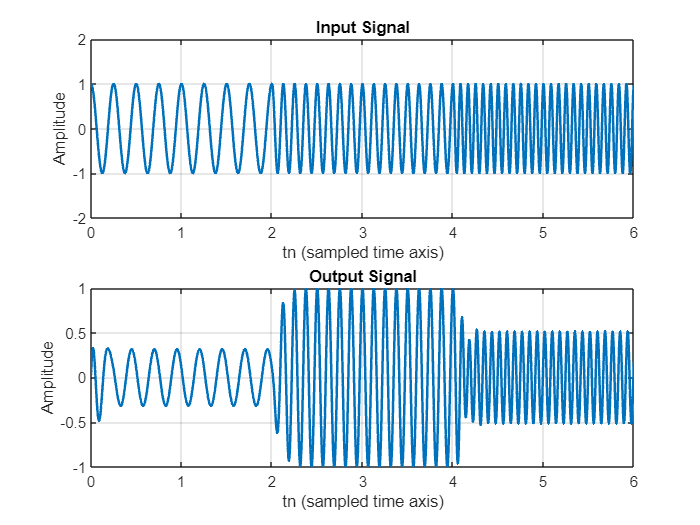

f1 = 4;
f2 = 8;
f3 = 12;
fs = 400;
T = 1/fs;
t = 0:T:6-T;
t1 = 0:T:2-T;
t2 = 0:T:4-T;
t3 = 0:T:6-T;
f = 0:1/f1:20;

x_t = cos(2*pi*f1*t).*(t>=0 & t<2) + cos(2*pi*f2*t).*(t>=2 & t<4) + cos(2*pi*f3*t).*(t>=4 & t<6);
y_n = filter(b1,[1 a1],x_t);
% H1
figure
subplot(2, 1, 1);
plot(t, x_t, "LineWidth", 1.5);
title("Input Signal")
xlabel("tn (sampled time axis)");
ylabel("Amplitude");
ylim([-2 2])
grid on
subplot(2, 1, 2);
plot(t, y_n, "LineWidth", 1.5);
title("Output Signal")
xlabel("tn (sampled time axis)");
ylabel("Amplitude");
grid on

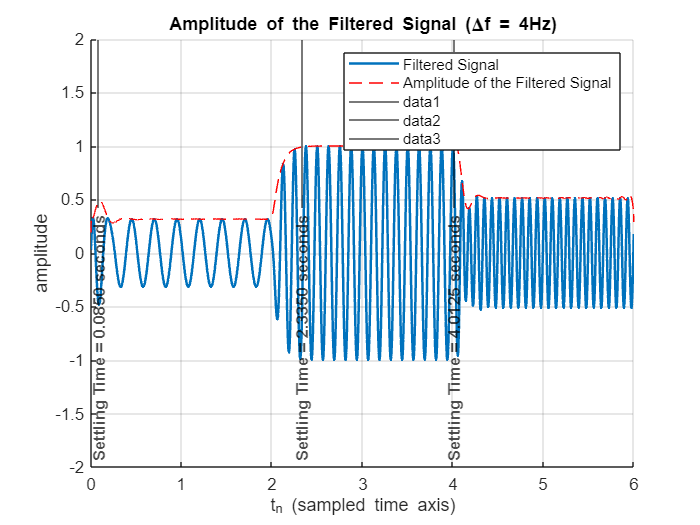

% Compute envelope using Hilbert transform
y_env = abs(hilbert(y_n));

% Compute theoretical |H(f)| at f1 and f3
[H, f] = freqz(b1, a1, 2048, fs);
Hf1 = abs(interp1(f, H, f1));   % |H(f1)| at 4 Hz
Hf2 = abs(interp1(f, H, f2));   % |H(f2)| at 8 Hz
Hf3 = abs(interp1(f, H, f3));   % |H(f3)| at 12 Hz

% Estimate envelope max in each segment
idx1 = find(t >= 0 & t < 2);
idx2 = find(t >= 2 & t < 4);
idx3 = find(t >= 4 & t < 6);
max_env1 = max(y_env(idx1));
max_env2 = max(y_env(idx2));
max_env3 = max(y_env(idx3));

% Find settling time (e.g., within 1% of steady-state)
threshold = 0.01;

settle1 = find(abs(y_env(idx1) - max_env1) < threshold, 1, 'first') / fs;
settle2 = find(abs(y_env(idx2) - max_env2) < threshold, 1, 'first') / fs + 2;
settle3 = find(abs(y_env(idx3) - max_env3) < threshold, 1, 'first') / fs + 4;

% Plot
figure; hold on
plot(t, y_n, 'DisplayName', 'Filtered Signal', "LineWidth", 1.5);
plot(t, y_env, 'r--', 'DisplayName', 'Amplitude of the Filtered Signal');

% Mark settling times
xline(settle1, 'k', ['Settling Time = ' num2str(settle1, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');
xline(settle2, 'k', ['Settling Time = ' num2str(settle2, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');
xline(settle3, 'k', ['Settling Time = ' num2str(settle3, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');

title('Amplitude of the Filtered Signal (\Deltaf = 4Hz)');
xlabel('t_n (sampled time axis)');
ylabel('amplitude');
legend();
grid on;
ylim([-2 2]);

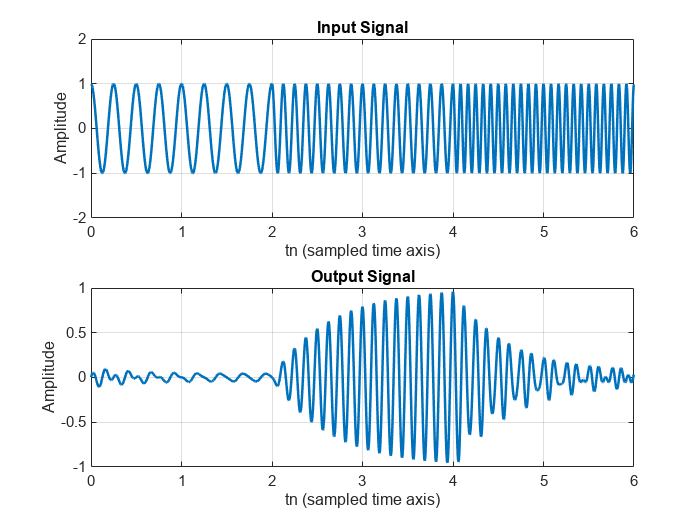



% -------------------

% H2
y_n_2 = filter(b2,[1 a2],x_t);

figure
subplot(2, 1, 1);
plot(t, x_t, "LineWidth", 1.5);
title("Input Signal")
xlabel("tn (sampled time axis)");
ylabel("Amplitude");
ylim([-2 2])
grid on
subplot(2, 1, 2);
plot(t, y_n_2, "LineWidth", 1.5);
title("Output Signal")
xlabel("tn (sampled time axis)");
ylabel("Amplitude");
grid on

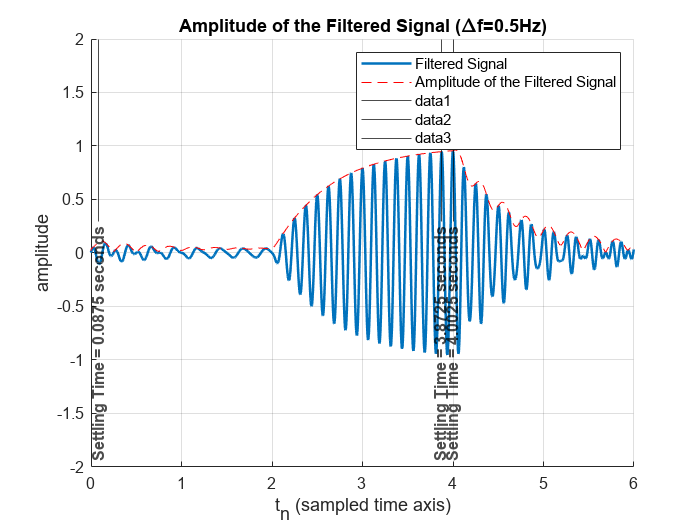

% Compute envelope using Hilbert transform
y_env = abs(hilbert(y_n_2));

% Compute theoretical |H(f)| at f1 and f3
[H, f] = freqz(b1, a1, 2048, fs);
Hf1 = abs(interp1(f, H, f1));   % |H(f1)| at 4 Hz
Hf2 = abs(interp1(f, H, f2));   % |H(f2)| at 8 Hz
Hf3 = abs(interp1(f, H, f3));   % |H(f3)| at 12 Hz

% Estimate envelope max in each segment
idx1 = find(t >= 0 & t < 2);
idx2 = find(t >= 2 & t < 4);
idx3 = find(t >= 4 & t < 6);
max_env1 = max(y_env(idx1));
max_env2 = max(y_env(idx2));
max_env3 = max(y_env(idx3));

% Find settling time (e.g., within 1% of steady-state)
threshold = 0.01;

settle1 = find(abs(y_env(idx1) - max_env1) < threshold, 1, 'first') / fs;
settle2 = find(abs(y_env(idx2) - max_env2) < threshold, 1, 'first') / fs + 2;
settle3 = find(abs(y_env(idx3) - max_env3) < threshold, 1, 'first') / fs + 4;

% Plot
figure; hold on
plot(t, y_n_2, 'DisplayName', 'Filtered Signal', "LineWidth", 1.5);
plot(t, y_env, 'r--', 'DisplayName', 'Amplitude of the Filtered Signal');

% Mark settling times
xline(settle1, 'k', ['Settling Time = ' num2str(settle1, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');
xline(settle2, 'k', ['Settling Time = ' num2str(settle2, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');
xline(settle3, 'k', ['Settling Time = ' num2str(settle3, '%.4f') ' seconds'], 'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','center', 'FontWeight','bold');

title('Amplitude of the Filtered Signal (\Deltaf=0.5Hz)');
xlabel('t_n (sampled time axis)');
ylabel('amplitude');
legend();
grid on;
ylim([-2 2]);

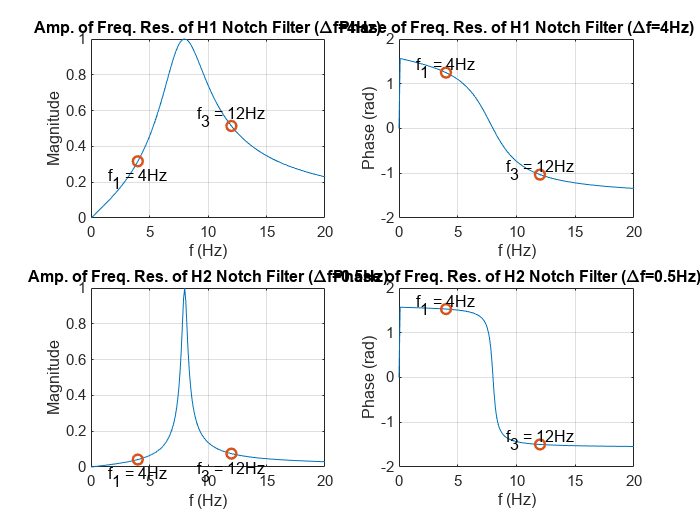



% -----------------------------------------------
[h1, w] = freqz(b1,[1 a1],f,fs);

[h2, w2] = freqz(b2,[1 a2],f,fs);


H1_f1 = abs(interp1(f, h1, f1));
H1_f3 = abs(interp1(f, h1, f3));
H2_f1 = abs(interp1(f, h2, f1));
H2_f3 = abs(interp1(f, h2, f3));

H1_f1_phase = angle(interp1(f, h1, f1));
H1_f3_phase = angle(interp1(f, h1, f3));
H2_f1_phase = angle(interp1(f, h2, f1));
H2_f3_phase = angle(interp1(f, h2, f3));

% Plot
figure;
subplot(2, 2, 1)
plot(f, abs(h1));
hold on;
plot([f1 f3], [H1_f1 H1_f3], 'o', 'LineWidth',1.5);
text(f1, H1_f1 - 0.1, 'f_1 = 4Hz', 'HorizontalAlignment', 'center');
text(f3, H1_f3 + 0.05, 'f_3 = 12Hz', 'HorizontalAlignment', 'center');
title("Amp. of Freq. Res. of H1 Notch Filter (\Deltaf=4Hz)")
xlabel("f (Hz)");
ylabel("Magnitude");
xlim([0 20]);
grid on

subplot(2, 2, 2);
plot(f, angle(h1));
hold on;
plot([f1 f3], [H1_f1_phase H1_f3_phase], 'o', 'LineWidth',1.5);
text(f1, H1_f1_phase + 0.1, 'f_1 = 4Hz', 'HorizontalAlignment', 'center');
text(f3, H1_f3_phase + 0.1, 'f_3 = 12Hz', 'HorizontalAlignment', 'center');
title("Phase of Freq. Res. of H1 Notch Filter (\Deltaf=4Hz)");
xlabel("f (Hz)");
ylabel("Phase (rad)");
xlim([0 20]);
grid on;

subplot(2, 2, 3)
plot(f, abs(h2));
hold on;
plot([f1 f3], [H2_f1 H2_f3], 'o', 'LineWidth',1.5);
text(f1, H2_f1 - 0.1, 'f_1 = 4Hz', 'HorizontalAlignment', 'center');
text(f3, H2_f3 - 0.1, 'f_3 = 12Hz', 'HorizontalAlignment', 'center');
title("Amp. of Freq. Res. of H2 Notch Filter (\Deltaf=0.5Hz)")
xlabel("f (Hz)");
ylabel("Magnitude");
xlim([0 20]);
grid on

subplot(2, 2, 4);
plot(f, angle(h2));
hold on;
plot([f1 f3], [H2_f1_phase H2_f3_phase], 'o', 'LineWidth',1.5);
text(f1, H2_f1_phase + 0.1, 'f_1 = 4Hz', 'HorizontalAlignment', 'center');
text(f3, H2_f3_phase + 0.1, 'f_3 = 12Hz', 'HorizontalAlignment', 'center');
title("Phase of Freq. Res. of H2 Notch Filter (\Deltaf=0.5Hz)");
xlabel("f (Hz)");
ylabel("Phase (rad)");
xlim([0 20]);
grid on;

threshold = 1/sqrt(2);

% --------------------------
idx_H1 = find(abs(h1) >= threshold-1e-2);
fL_H1 = f(idx_H1(1));
fH_H1 = f(idx_H1(end));
BW_H1 = fH_H1 - fL_H1;

% --------------------------
idx_H2 = find(abs(h2) >= threshold-6e-2);
fL_H2 = f(idx_H2(1));
fH_H2 = f(idx_H2(end));
BW_H2 = fH_H2 - fL_H2;

fprintf('--- H1 Notch Filter ---\n');

--- H1 Notch Filter ---



fprintf('fL = %.4f Hz, fH = %.4f Hz, Δf = %.4f Hz\n', fL_H1, fH_H1, BW_H1);

fL = 6.2500 Hz, fH = 10.2539 Hz, Δf = 4.0039 Hz



fprintf('--- H2 Notch Filter ---\n');

--- H2 Notch Filter ---



fprintf('fL = %.4f Hz, fH = %.4f Hz, Δf = %.4f Hz\n', fL_H2, fH_H2, BW_H2);

fL = 7.7148 Hz, fH = 8.2031 Hz, Δf = 0.4883 Hz


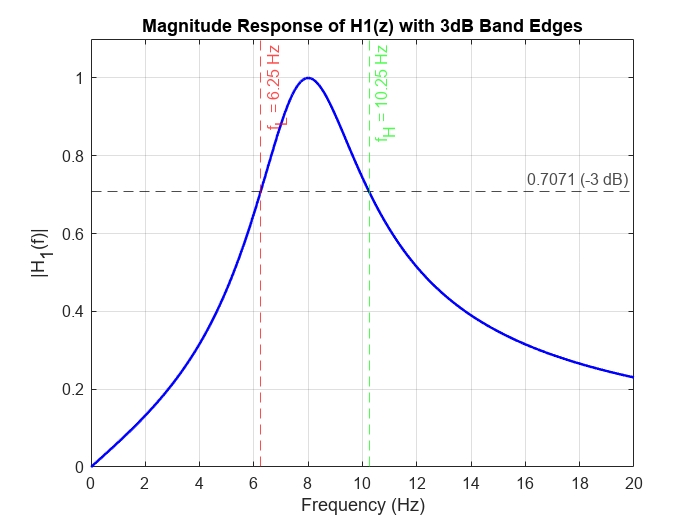


figure;
plot(f, abs(h1), 'b', 'LineWidth', 1.5); hold on;
yline(threshold, 'k--', '0.7071 (-3 dB)');
xline(fL_H1, 'r--', ['f_L = ' num2str(fL_H1, '%.2f') ' Hz']);
xline(fH_H1, 'g--', ['f_H = ' num2str(fH_H1, '%.2f') ' Hz']);
title('Magnitude Response of H1(z) with 3dB Band Edges');
xlabel('Frequency (Hz)');
ylabel('|H_1(f)|');
grid on;
xlim([0 20]);
ylim([0 1.1]);

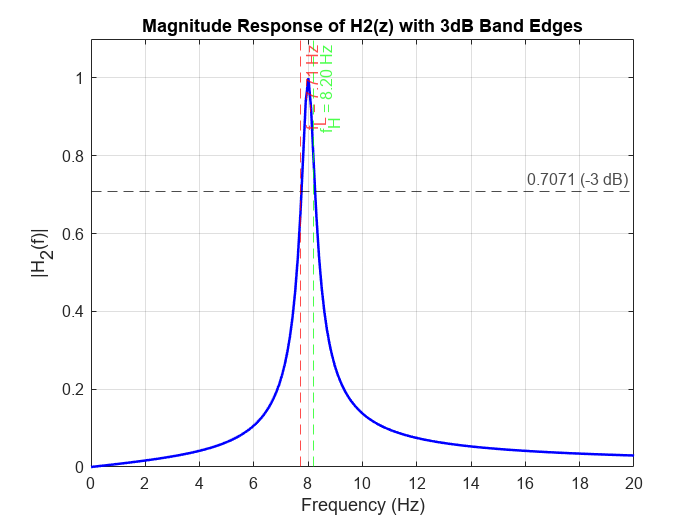

% --------------------------

figure;
plot(f, abs(h2), 'b', 'LineWidth', 1.5); hold on;
yline(threshold, 'k--', '0.7071 (-3 dB)');
xline(fL_H2, 'r--', ['f_L = ' num2str(fL_H2, '%.2f') ' Hz']);
xline(fH_H2, 'g--', ['f_H = ' num2str(fH_H2, '%.2f') ' Hz']);
title('Magnitude Response of H2(z) with 3dB Band Edges');
xlabel('Frequency (Hz)');
ylabel('|H_2(f)|');
grid on;
xlim([0 20]);
ylim([0 1.1]);